# Sampling and Aliasing

## Sampling and Reconstruction at the Nyquist Frequency

Consider the analog signal $x_a(t) = \cos(20\,\pi\,t + \theta)$for $0 \le t \le 1$. It is sampled at $T_s = 0.05 $second intervals to obtain x[n]. Let $\theta = 0, \, \pi/6, \, \pi/4, \, \pi/2.$For each value of the $\theta$ values, perform the following.

- Plot $x_a(t)$ and superimpose x[n] on top of it using the plot(n,x,'o') function.

- Reconstruct the analog signal  from the samples x[n] using the sinc interpolation. Use $\Delta\,t = 0.001$, and superimpiose x[n] on it.

- You should observe that the resultant reconstruction in each case has the correct frequency but a different amplitude. Explain this observation. Comment on the role of the phase of $x_a(t)$on the sampling and reconstruction of signals.

Put your work here:

1-1. Plot $x_a(t)$ and superimpose x[n] on top of it using the plot(n,x,'o') function.

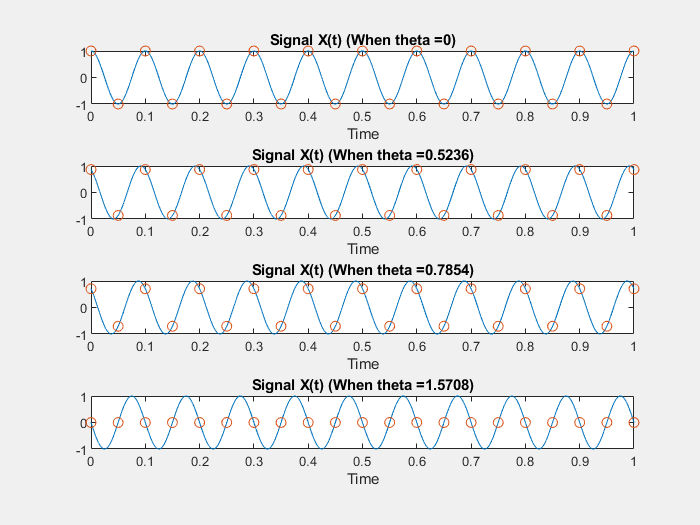

close all 
clear all
fsref = 100000;
tref = (0:1/fsref:1);
fs = 20 ; % Sample signal at 20Hz
ts= (0:1/fs:1) ; % Time interval is 0.05sec
f = 10;

i = 1;
figure
for theta = [0,pi/6,pi/4,pi/2]
    sig = cos(2*pi*f*ts+ theta);
    sig_ref = cos(2*pi*f*tref + theta); % Reference signal 
    set(gcf,'Visible','On')
    subplot(4,1,i)
    plot(tref,sig_ref)
    hold on
    plot(ts, sig, 'o')
    titleName = strcat('Signal X(t) (When theta = ',num2str(theta),')');
    title(titleName); 
    xlabel('Time')
    i = i + 1;

end

1-2. Reconstruct the analog signal  from the samples x[n] using the sinc interpolation. Use $\Delta\,t = 0.001$, and superimpiose x[n] on it.

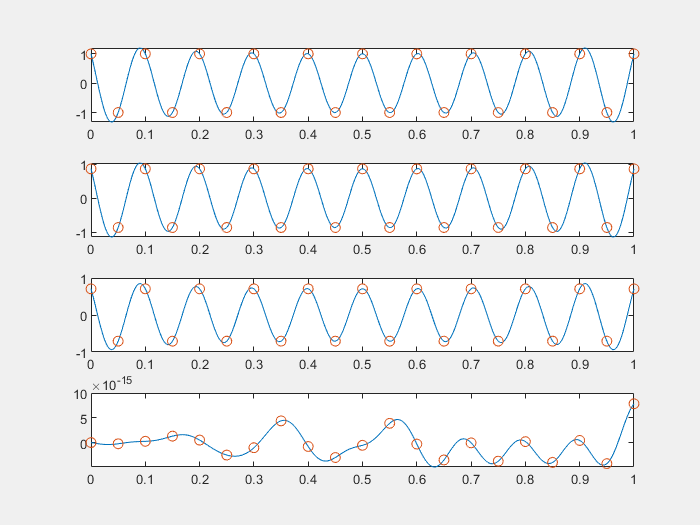

sinc_arg =          0   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000  -20.0000
    0.0200   -0.9800   -1.9800   -2.9800   -3.9800   -4.9800   -5.9800   -6.9800   -7.9800   -8.9800   -9.9800  -10.9800  -11.9800  -12.9800  -13.9800  -14.9800  -15.9800  -16.9800  -17.9800  -18.9800  -19.9800
    0.0400   -0.9600   -1.9600   -2.9600   -3.9600   -4.9600   -5.9600   -6.9600   -7.9600   -8.9600   -9.9600  -10.9600  -11.9600  -12.9600  -13.9600  -14.9600  -15.9600  -16.9600  -17.9600  -18.9600  -19.9600
    0.0600   -0.9400   -1.9400   -2.9400   -3.9400   -4.9400   -5.9400   -6.9400   -7.9400   -8.9400   -9.9400  -10.9400  -11.9400  -12.9400  -13.9400  -14.9400  -15.9400  -16.9400  -17.9400  -18.9400  -19.9400
    0.0800   -0.9200   -1.9200   -2.9200   -3.9200   -4.9200   -5.9200   -6.9200   -7.9200   -8.9200   -9.9200  -10.9200  -11.9200  -12.9200  -13

sinc_arg =          0   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000  -20.0000
    0.0200   -0.9800   -1.9800   -2.9800   -3.9800   -4.9800   -5.9800   -6.9800   -7.9800   -8.9800   -9.9800  -10.9800  -11.9800  -12.9800  -13.9800  -14.9800  -15.9800  -16.9800  -17.9800  -18.9800  -19.9800
    0.0400   -0.9600   -1.9600   -2.9600   -3.9600   -4.9600   -5.9600   -6.9600   -7.9600   -8.9600   -9.9600  -10.9600  -11.9600  -12.9600  -13.9600  -14.9600  -15.9600  -16.9600  -17.9600  -18.9600  -19.9600
    0.0600   -0.9400   -1.9400   -2.9400   -3.9400   -4.9400   -5.9400   -6.9400   -7.9400   -8.9400   -9.9400  -10.9400  -11.9400  -12.9400  -13.9400  -14.9400  -15.9400  -16.9400  -17.9400  -18.9400  -19.9400
    0.0800   -0.9200   -1.9200   -2.9200   -3.9200   -4.9200   -5.9200   -6.9200   -7.9200   -8.9200   -9.9200  -10.9200  -11.9200  -12.9200  -13

sinc_arg =          0   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000  -20.0000
    0.0200   -0.9800   -1.9800   -2.9800   -3.9800   -4.9800   -5.9800   -6.9800   -7.9800   -8.9800   -9.9800  -10.9800  -11.9800  -12.9800  -13.9800  -14.9800  -15.9800  -16.9800  -17.9800  -18.9800  -19.9800
    0.0400   -0.9600   -1.9600   -2.9600   -3.9600   -4.9600   -5.9600   -6.9600   -7.9600   -8.9600   -9.9600  -10.9600  -11.9600  -12.9600  -13.9600  -14.9600  -15.9600  -16.9600  -17.9600  -18.9600  -19.9600
    0.0600   -0.9400   -1.9400   -2.9400   -3.9400   -4.9400   -5.9400   -6.9400   -7.9400   -8.9400   -9.9400  -10.9400  -11.9400  -12.9400  -13.9400  -14.9400  -15.9400  -16.9400  -17.9400  -18.9400  -19.9400
    0.0800   -0.9200   -1.9200   -2.9200   -3.9200   -4.9200   -5.9200   -6.9200   -7.9200   -8.9200   -9.9200  -10.9200  -11.9200  -12.9200  -13

sinc_arg =          0   -1.0000   -2.0000   -3.0000   -4.0000   -5.0000   -6.0000   -7.0000   -8.0000   -9.0000  -10.0000  -11.0000  -12.0000  -13.0000  -14.0000  -15.0000  -16.0000  -17.0000  -18.0000  -19.0000  -20.0000
    0.0200   -0.9800   -1.9800   -2.9800   -3.9800   -4.9800   -5.9800   -6.9800   -7.9800   -8.9800   -9.9800  -10.9800  -11.9800  -12.9800  -13.9800  -14.9800  -15.9800  -16.9800  -17.9800  -18.9800  -19.9800
    0.0400   -0.9600   -1.9600   -2.9600   -3.9600   -4.9600   -5.9600   -6.9600   -7.9600   -8.9600   -9.9600  -10.9600  -11.9600  -12.9600  -13.9600  -14.9600  -15.9600  -16.9600  -17.9600  -18.9600  -19.9600
    0.0600   -0.9400   -1.9400   -2.9400   -3.9400   -4.9400   -5.9400   -6.9400   -7.9400   -8.9400   -9.9400  -10.9400  -11.9400  -12.9400  -13.9400  -14.9400  -15.9400  -16.9400  -17.9400  -18.9400  -19.9400
    0.0800   -0.9200   -1.9200   -2.9200   -3.9200   -4.9200   -5.9200   -6.9200   -7.9200   -8.9200   -9.9200  -10.9200  -11.9200  -12.9200  -13

% Perform the sinc reconstruction and compare with reference signal
n = (1:21) ;    % Use 20 samples for 1 s
T = 0.001 ;     %sampling interval is 1/1000
tt = (0:T:1) ;
f = 10;

i = 1;
figure
for theta = [0,pi/6,pi/4,pi/2]
sig = cos(2*pi*f*ts+ theta);
% create the sinc argument - use broadcasting to get an array
sinc_arg = fs*(tt.' - (n-1)*(1/fs))   %fs = 20;

% implement the sinc reconstruction formula
sig_recon = sum( bsxfun(@times,sinc(sinc_arg),sig(1:21)) ,2 ) ;

% plot and compare with the reference signal
set(gcf,'Visible','On')
subplot(4,1,i)
plot(tt, sig_recon);
hold on
plot(ts, sig, 'o')
i = i + 1;
end

1-3. Explanations 

Although sample rate is enough, the theta will affect the result of reconstruction. For example, in plot of question 1-1, when theta is pi/2, all sampling values of x[n] are around zero, which makes the reconstruction has the correct frequency but a different amplitude. Hence, the phase of $x_a(t)$will influence the sampling and reconstruction of signals. 

## Aliasing with Images

We explore aliasing with sounds in Python. Here we explore aliasing with images.

Show an excellent image for the study of aliasing.

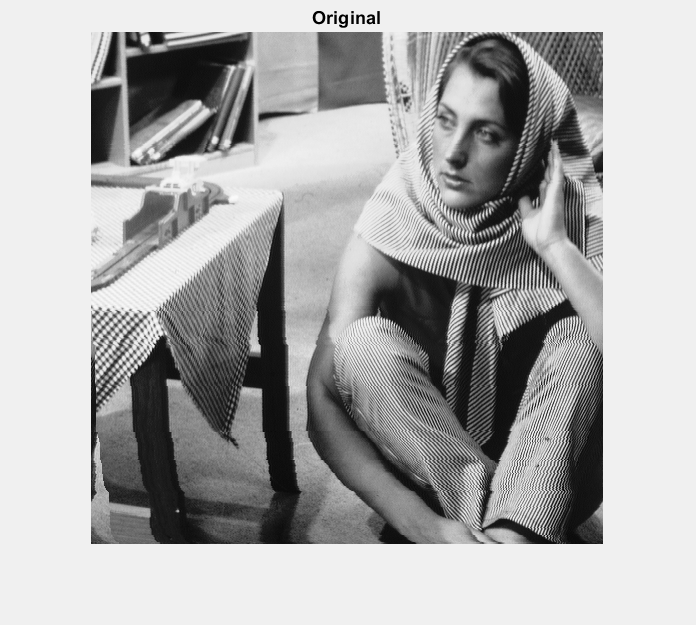

clc
clear all
close all

Im1 = imread('barbara_gray.bmp') ;
figure
set(gcf,'Visible','On')
imshow(Im1)
title('Original')

[height, width, depth] = size(Im1) 

height = 512

width = 512

depth = 1

Downsample the image with no prefiltering

% in case bit depth is three (if trying other images)
Im2 = Im1(:,:,1) ;

% downsample no prefiltering
M = 4 ;
% write code to downsample the image by a factor of M
% put code here
% Im3 = 
% plot downsampled image
figure
set(gcf,'Visible','On')
imshow(Im3)

Undefined function or variable 'Im3'.

title(['Downsample by ' num2str(M) ':No prefiltering']) ;

% reconstruct to original size
Im4 = imresize(Im3, [height,width],'bicubic')
figure
set(gcf,'Visible','On')
imshow(Im4)
title(['Reconstructed from downsample image: no prefiltering'])

Downsample with low-pass prefiltering

% downsample by a factor of M, after prefiltering
% apply a Gaussian filter to the image
% use the fspecial function to create a Gaussian filter
% explore reasonable values for the filter parameters
% use imfilter to apply the filter to the original image.
% put your code here

% plot the downsampled image with prefiltering
figure
set(gcf,'Visible','On')
imshow(Im6)
title(['Downsampled by ' num2str(M) ' After prefiltering']) ;

Im7 = imresize(Im6,[height,width],'bicubic') ;
figure
set(gcf,'Visible','On')
imshow(Im7)
title('Reconstructed from downsampled image: with prefiltering')


## Explain your Observations

Explain why aliasing should occur. Explain what you observe with aliasing. Explain why there is an improvement with the application of a prefilter.